## **MATLAB Code for ENME 561-661**

## Study Response Characteristics of a Parallel PID controller and Manual PID Gain Tuning using MATLAB

clear;clc;close all;

TF of the Plant: 1/(s+1)^3. Feel free to choose different plants

t = 0:0.1:40;
plant = zpk([],[-1 -1 -1],1); %3rd order plant

What is the step response with only a unity feedback (i.e. k_p=1, no derivative and no integral actions )?

[y0,t0] = step(feedback(plant,1),t);

Plot data:

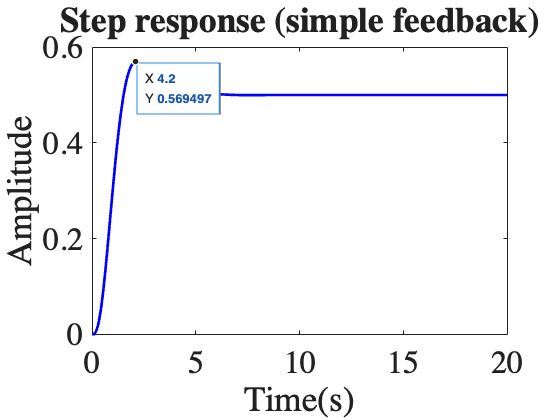

figure;
plot(t, y0,'b', 'LineWidth',2);
title('Step response (simple feedback)')
xlabel('Time(s)')
ylabel('Amplitude')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24)

Compute stepinfo: [https://www.mathworks.com/help/control/ref/dynamicsystem.stepinfo.html#mw_05d9910f-a5e2-437a-a344-17d58cbcb0a4](https://www.mathworks.com/help/control/ref/dynamicsystem.stepinfo.html#mw_05d9910f-a5e2-437a-a344-17d58cbcb0a4) 

Method 1:

stepinfo(feedback(plant,1))

ans = struct with fields:
         RiseTime: 1.8723
    TransientTime: 8.3956
     SettlingTime: 8.3956
      SettlingMin: 0.4544
      SettlingMax: 0.5695
        Overshoot: 13.9071
       Undershoot: 0
             Peak: 0.5695
         PeakTime: 4.2368


Method 2:

yfinal=1;
yinit=0;
stepinfo(y0,t0,yfinal,yinit)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: 0
       Undershoot: 0
             Peak: 0.5695
         PeakTime: 4.2000


Which method is correct? 1 or 2? Why?

## P controller

Here three different values for kp are chosen, feel free to change the values and observe effects of kp. 

recall: C= pid(Kp, Ki, Kd)

C1 = pid(1,0,0);
C2 = pid(2,0,0);
C3 = pid(3,0,0);

[y1,t1] = step(feedback(C1*plant,1),t);
stepinfo(y1,t1,yfinal,yinit)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: 0
       Undershoot: 0
             Peak: 0.5695
         PeakTime: 4.2000



[y2,t2] = step(feedback(C2*plant,1),t);
stepinfo(y2,t2,yfinal,yinit)

ans = struct with fields:
         RiseTime: NaN
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: NaN
      SettlingMax: NaN
        Overshoot: 0
       Undershoot: 0
             Peak: 0.8656
         PeakTime: 3.4000



[y3,t3] = step(feedback(C3*plant,1),t);
stepinfo(y3,t3,yfinal,yinit)

ans = struct with fields:
         RiseTime: 1.4594
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.5899
      SettlingMax: 1.0730
        Overshoot: 7.2999
       Undershoot: 0
             Peak: 1.0730
         PeakTime: 2.9000


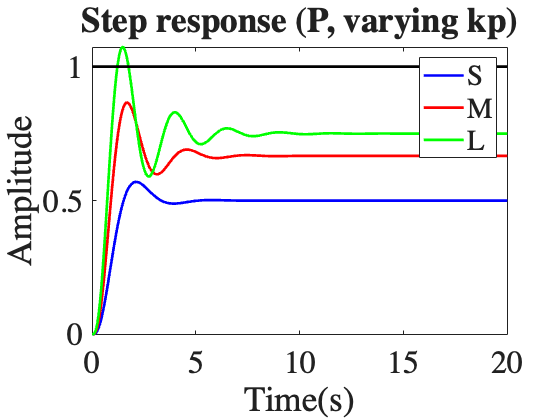


plot(t, y1,'b', 'LineWidth',2); hold on
plot(t, y2,'r', 'LineWidth',2); hold on
plot(t, y3,'g', 'LineWidth',2); hold on
plot(t, ones(1,length(t)),'k', 'LineWidth',2); 
legend('S','M','L')
title('Step response (P, varying kp)')
xlabel('Time(s)')
ylabel('Amplitude')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24)

## PI controller

Here three different values for ki are chosen, and kp is kept constant. Feel free to change the values and observe the effects of ki.

recall: C= pid(Kp, Ki, Kd)

C4 = pid(1,0.1,0)

C4 =              1 
  Kp + Ki * ---
             s 

  with Kp = 1, Ki = 0.1
 
Continuous-time PI controller in parallel form.


C5 = pid(1,0.5,0);

C5 =              1 
  Kp + Ki * ---
             s 

  with Kp = 1, Ki = 0.5
 
Continuous-time PI controller in parallel form.


C6 = pid(1,1,0);

C6 =              1 
  Kp + Ki * ---
             s 

  with Kp = 1, Ki = 1
 
Continuous-time PI controller in parallel form.


figure;
[y4,t4] = step(feedback(C4*plant,1),t);
stepinfo(y4,t4,yfinal,yinit)

ans = struct with fields:
         RiseTime: 28.5294
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.9004
      SettlingMax: 0.9430
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9430
         PeakTime: 40



[y5,t5] = step(feedback(C5*plant,1),t);
stepinfo(y5,t5,yfinal,yinit)

ans = struct with fields:
         RiseTime: 2.3649
    TransientTime: 11.1556
     SettlingTime: 11.1556
      SettlingMin: 0.9259
      SettlingMax: 1.1351
        Overshoot: 13.5117
       Undershoot: 0
             Peak: 1.1351
         PeakTime: 5.3000



[y6,t6] = step(feedback(C6*plant,1),t);
stepinfo(y6,t6,yfinal,yinit)

ans = struct with fields:
         RiseTime: 1.7277
    TransientTime: 30.9381
     SettlingTime: 30.9381
      SettlingMin: 0.6758
      SettlingMax: 1.5436
        Overshoot: 54.3551
       Undershoot: 0
             Peak: 1.5436
         PeakTime: 4.8000


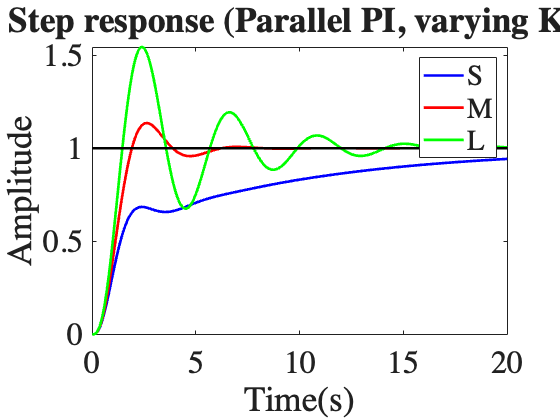


plot(t, y4,'b', 'LineWidth',2); hold on
plot(t, y5,'r', 'LineWidth',2); hold on
plot(t, y6,'g', 'LineWidth',2); hold on;
plot(t, ones(1,length(t)),'k', 'LineWidth',2); 
legend('S','M','L')
title('Step response (Parallel PI, varying KI)')
xlabel('Time(s)')
ylabel('Amplitude')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24)

## PID controller

Here three different values for kd are chosen, and kp and ki are kept constant. Feel free to change the values and observe the effects of kd.


C7 = pid(0.5,1,0.1)

C7 =              1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.5, Ki = 1, Kd = 0.1
 
Continuous-time PID controller in parallel form.


C8 = pid(0.5,1,1);

C8 =              1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.5, Ki = 1, Kd = 1
 
Continuous-time PID controller in parallel form.


C9 = pid(0.5,1,10);

C9 =              1          
  Kp + Ki * --- + Kd * s
             s          

  with Kp = 0.5, Ki = 1, Kd = 10
 
Continuous-time PID controller in parallel form.


figure;
[y7,t7] = step(feedback(C7*plant,1),t);
stepinfo(y7,t7,yfinal,yinit)

ans = struct with fields:
         RiseTime: 1.9757
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.4955
      SettlingMax: 1.6649
        Overshoot: 66.4909
       Undershoot: 0
             Peak: 1.6649
         PeakTime: 5.5000



[y8,t8] = step(feedback(C8*plant,1),t);
stepinfo(y8,t8,yfinal,yinit)

ans = struct with fields:
         RiseTime: 2.6835
    TransientTime: 35.6457
     SettlingTime: 35.6457
      SettlingMin: 0.7697
      SettlingMax: 1.3972
        Overshoot: 39.7189
       Undershoot: 0
             Peak: 1.3972
         PeakTime: 6.1000



[y9,t9] = step(feedback(C9*plant,1),t);
stepinfo(y9,t9,yfinal,yinit)

ans = struct with fields:
         RiseTime: 0.6052
    TransientTime: NaN
     SettlingTime: NaN
      SettlingMin: 0.7047
      SettlingMax: 1.1401
        Overshoot: 14.0149
       Undershoot: 0
             Peak: 1.1401
         PeakTime: 13.5000


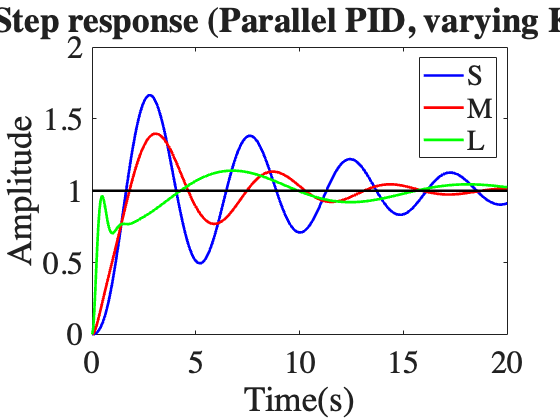


plot(t, squeeze(y7),'b', 'LineWidth',2); hold on
plot(t, squeeze(y8),'r', 'LineWidth',2); hold on
plot(t, squeeze(y9),'g', 'LineWidth',2); hold on;
plot(t, ones(1,length(t)),'k', 'LineWidth',2); 
legend('S','M','L')
title('Step response (Parallel PID, varying Kd)')
xlabel('Time(s)')
ylabel('Amplitude')
a = get(gca,'XTickLabel');
set(gca,'XTickLabel',a,'FontName','Times','fontsize',24)